- Random Variables

- Definition

Consider a probality person's mind as 


$$Mind =\{happy, sad \} \\
Probabilty ({happy})  = 0.7.\ probability({sad}) = 0.3 $$


Define a function $X$ from the sample points to a real number  


$$X(happy) = 1, X(sad) = 0$$


Then 


$$P(X=1)  = Prob({happy) = 0.6 , P(X=0) = Prob({sad}) = 0.4$$


We call $X$a "Random Variable"

        2. Concept 

      - a random variable is a function from the sample space into a real number

      - So it is better to say probabilty of {happy}, {sad}  or {head} , {tail} rather then

          
$$P(X=a) \  or \ P(X=b)$$


       3. Some terminolory 

-      probabilty distribution function (PDF) :    

 
$$F_x (X <= a)  = Probability (X<= a)$$


        Sometimes it is called the cumulatice probability function 

-      probability density function (pdf) : $f_X (x)$

  
$$f(x) = dF_X (x) / dx$$


        hence 

                   
$$Probability (X<= a) = F_x (x=a)   \\
= \int_{-\infty}^{a} f_X (x)dx
$$


- mean : $m_x  = E[X]$


$$E[X] = \int_{-\infty}^{\infty} x f(x) dx$$


- variance : $\sigma _X ^2  = E[(X-m_x)^2 ]$


$$E[(X-m_x )^2] = \int_{-\infty}^{\infty}(x-m_x )^2 dx $$


- general expectation: $E[g(X)]$


$$E[g(X)]= \int _{-\infty}^{\infty} g(x) f(x) dx$$


        4. Example 

       ** 4.1 uniform random number generator **

         In matlab, random number , which is the same to random varible, but especially in discrete   

       random variable.  The are some general random variables defined for simulation. Consider $X $to  

       be a uniform  random variable,  The Probability density function          


$$f_X (x) =f(x) =
\begin{cases}
1,    0 <x <1 \\
0,  \ other wise  
\end{cases}$$


        The CDF (Probability distribution function)


$$F_X (x) =F(x) =
\begin{cases}
0,  \ \   x <0 \\
x,  \ \  0<=x<1 \\
1,  \ \   1<x \end{cases}$$


       In matlab,"rand" is a random number generator. type "help rand".Using "rand" cmd to see the pdf  comparing histogram 

    2) Using "rand"

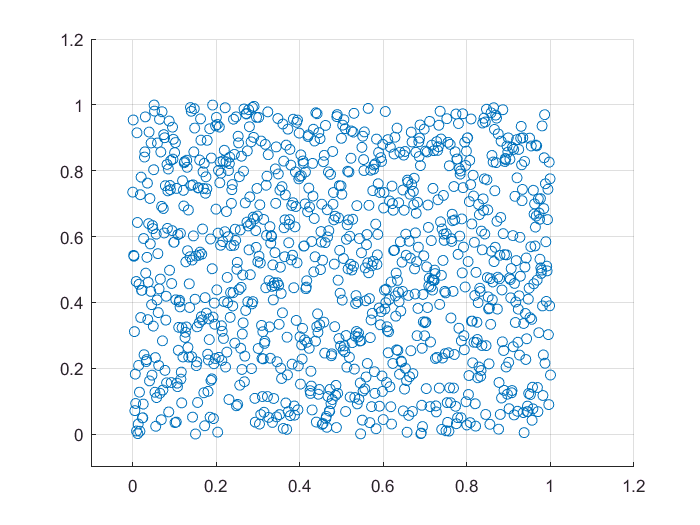

clear all;clc
a =0; b= 1;
x =linspace(a,b,1000);
sz = size(x);
y =rand(sz);
scatter(x,y); grid on;
axis([-0.1  1.2 -0.1 1.2])

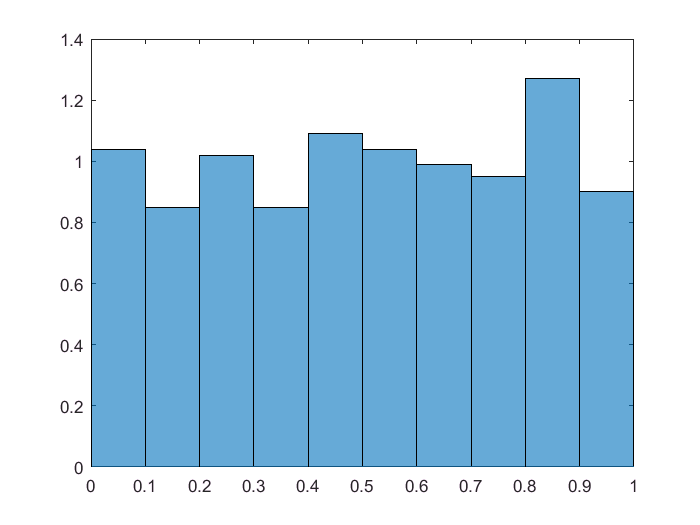

histogram(y,'Normalization', 'pdf');

    The "pdf by normalization" is not perfect uniform. 

    3) Using "unifpdf" 

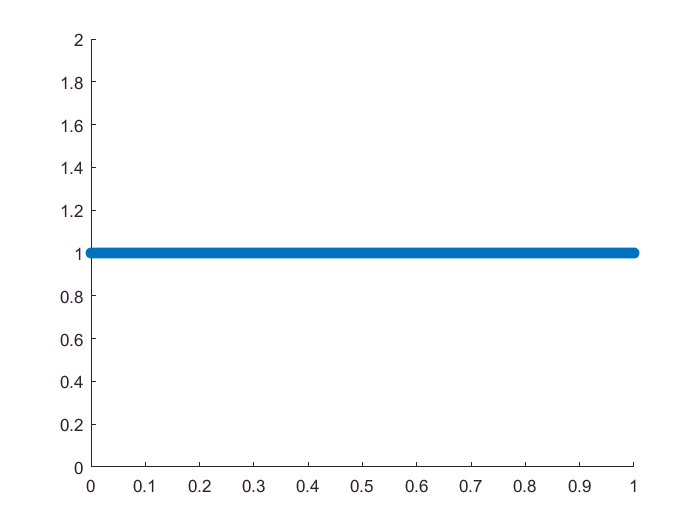

y_uni = unifpdf(x,a,b);   % uniform density function correspondig to sampling points t
figure()
scatter(x,y_uni)

% histogram(y_uni,'Normalization','pdf')

    4) mean, variance 

   the mean is

     
$$m_X  = \int xf(x) dx  = \int_{0}^{1}(x)(1) dx = 1/2 $$


    and the variance is 


$$\sigma_X^2  = \int_{0}^{1}(x-1/2)^2  (1)dx = 1/12
$$


m=mean(x.*y_uni)*(b-a)

m = 0.5000

vari = mean((x-m).^2.*y_uni)*(b-a)

vari = 0.0835

1/12

ans = 0.0833

      5) Application 

   In digital readings, it has the resolution $d$, such as if a measured data is $a$ which means the real

   value $x$ is in the range 


$$ a-d/2  <= x <  a+ d/2 $$


  so that, the real value is a random variable with a uniform pdf.  

      **4.2 Exponential pdf**

    
$$f_X (x) =  \begin{cases}  1/\lambda e^{-\lambda x} , x<= x \\  0 \ other wise \end{cases} $$


     where $\lambda >0$

       1) the mean: 

  
$$E[X]  = \int _{0}^{\infty}x \lambda  e^{-\lambda x} dx \\
= 1/\lambda $$


      2) variance: 


$$E[(X-m)^2] = \int(x-m)^2 f(x)dx = 1/\lambda ^2 $$


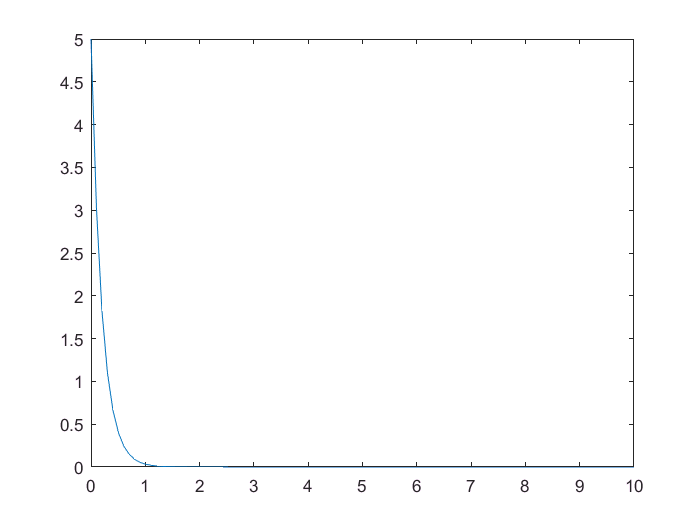

 clear all; clc;
 a =0; b = 10;
 x =linspace(a,b,100); % the number of sampling = 100
 lambda = 5;
 y = exppdf(x,1/lambda);
 figure( )
 plot(x,y)

 m =mean(x.*y)*(b-a)

m = 0.1938

 vari = mean((x-m).^2.*y)*(b-a)

vari = 0.0514

 1/(lambda)^2  

ans = 0.0400

  If then number of sampling is increasing, the calculated is the same to the analytic. 

   3) application;

     the failure probability is similar to the exponential pdf. You may experience that a new bulb is working for long time if the bulb is not broken in a first short time.

**    4.3 Gaussian R.V. **


$$f(x)  = \frac{1}_{\sigma \sqrt {2\pi}}  e^{- 
(\frac{x -\mu}_{2\sigma ^2 })^2$$


   1) mean : $m_X = \mu$

       
$$\mu = \int _{-\infty }^{\infty} x f(x) dx$$


   2) variance : $\sigma _X ^2  = \sigma ^2 $


$$\sigma = \int(x-\mu)^2 f(x) dx$$


   3) Applications.

    If it is not specified, the measurement is supposed to a gaussian!!

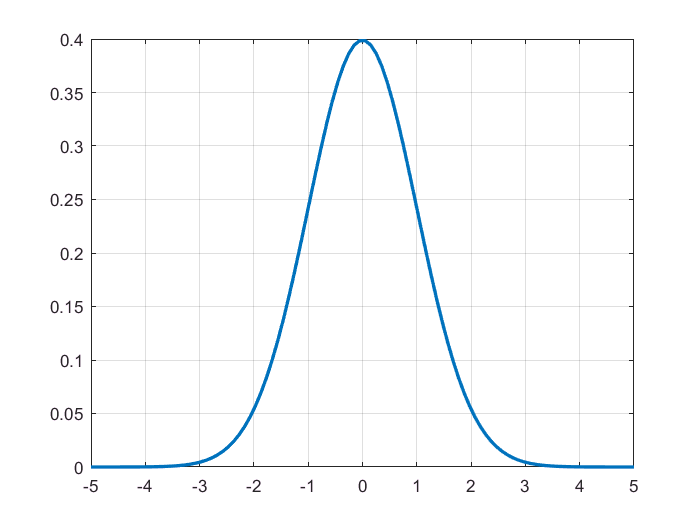

clear all; clc;
a= -5; b= 5; d = 0.1;
% x = a:d:b;
x = linspace(a,b,100);
% x = [-2, -1 ,0];
m = 0;
sig = 1;
z = normpdf(x,m,sig);
plot(x,z,'linewidth',2); grid on